# **1 задание**

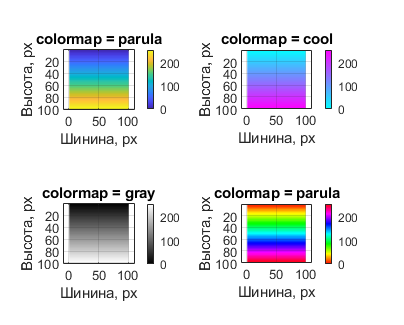

N = 100;

A1 = uint8(zeros(N));

for i = 1 : N
    for j = 1 : N
        A1(i,j) = 255 / N * i;
    end
end

A2 = A1;
A3 = A1;
A4 = A1;

f1 = figure('Position', [50, 50, 1050, 850]);

ax1 = subplot(2,2,1);
image(A1)
axis('equal')
grid on
colormap(ax1, 'parula');
colorbar
title('colormap = parula')
xlabel('Шинина, px')
ylabel('Высота, px')

ax2 = subplot(2,2,2);
image(A2)
axis('equal')
grid on
colormap(ax2, 'cool');
colorbar
title('colormap = cool')
xlabel('Шинина, px')
ylabel('Высота, px')

ax3 = subplot(2,2,3);
image(A3)
axis('equal')
grid on
colormap(ax3, 'gray');
colorbar
title('colormap = gray')
xlabel('Шинина, px')
ylabel('Высота, px')


ax4 = subplot(2,2,4);
image(A4)
axis('equal')
grid on
colormap(ax4, 'hsv');
colorbar
title('colormap = parula')
xlabel('Шинина, px')
ylabel('Высота, px')


saveas(f1, 'first_task.png')

# **Задание 2**

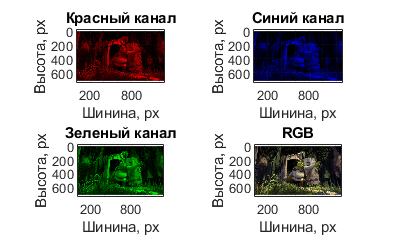

mem = imread('Shrek.jpg');
black = uint8(zeros(size(mem(:,:,1))));

red = cat(3, mem(:,:,1), black, black);
green = cat(3, black, mem(:,:,1), black);
blue = cat(3, black, black, mem(:,:,1));

f2 = figure('Position', [50, 50, 1250, 750]);

subplot(2,2,1)
image(red)
axis('equal')
grid on
title('Красный канал')
xlabel('Шинина, px')
ylabel('Высота, px')

subplot(2,2,2)
image(blue)
axis('equal')
grid on
title('Синий канал')
xlabel('Шинина, px')
ylabel('Высота, px')

subplot(2,2,3)
image(green)
axis('equal')
grid on
title('Зеленый канал')
xlabel('Шинина, px')
ylabel('Высота, px')

subplot(2,2,4)
image(mem)
axis('equal')
grid on
title('RGB')
xlabel('Шинина, px')
ylabel('Высота, px')

saveas(f2, 'second_task.png')

# **Задание 3**

mem = imread('Shrek.jpg');

brightness = uint8(mean(mem, 3));
red = uint8(mem(:,:,1));
green = uint8(mem(:,:,2));
blue = uint8(mem(:,:,3));

f3 = figure('Position', [50, 50, 850, 1050]);

nBins = 100;

subplot(2,1,1)
image(mem);
axis('equal')
grid on
title('SHREK!')
xlabel('Шинина, px')
ylabel('Высота, px')

subplot(2,1,2);


h2 = histogram(red, nBins, 'FaceColor', 'red')

h2 =   Histogram with properties:

             Data: [720×1280 uint8]
           Values: [72683 41993 27274 39942 28018 36572 22105 28399 17049 25121 25511 17726 26268 17409 24423 15169 21878 14201 20788 19554 12990 18458 11663 17576 11979 18151 11565 16474 10621 15072 14337 9155 12610 7498 10351 6541 9605 6095 9093 … ]
          NumBins: 100
         BinEdges: [0 2.5500 5.1000 7.6500 10.2000 12.7500 15.3000 17.8500 20.4000 22.9500 25.5000 28.0500 30.6000 33.1500 35.7000 38.2500 40.8000 43.3500 45.9000 48.4500 51.0000 53.5500 56.1000 58.6500 61.2000 63.7500 66.3000 68.8500 71.4000 73.9500 … ]
         BinWidth: 2.5500
        BinLimits: [0 255.0000]
    Normalization: 'count'
        FaceColor: [1 0 0]
        EdgeColor: [0 0 0]

  Show 

hold on
h3 = histogram(green, nBins, 'FaceColor', 'green')

h3 =   Histogram with properties:

             Data: [720×1280 uint8]
           Values: [65813 41257 26423 41712 29104 42468 25360 32155 18649 26961 24217 15201 23047 15738 23780 15587 22624 14274 20615 19858 12983 18962 12270 18342 11781 17533 11449 16831 10689 14965 13981 8754 12684 8445 12440 7568 10922 6614 9002 … ]
          NumBins: 100
         BinEdges: [0 2.5500 5.1000 7.6500 10.2000 12.7500 15.3000 17.8500 20.4000 22.9500 25.5000 28.0500 30.6000 33.1500 35.7000 38.2500 40.8000 43.3500 45.9000 48.4500 51.0000 53.5500 56.1000 58.6500 61.2000 63.7500 66.3000 68.8500 71.4000 73.9500 … ]
         BinWidth: 2.5500
        BinLimits: [0 255.0000]
    Normalization: 'count'
        FaceColor: [0 1 0]
        EdgeColor: [0 0 0]

  Show 

hold on
h4 = histogram(blue, nBins, 'FaceColor', 'blue')

h4 =   Histogram with properties:

             Data: [720×1280 uint8]
           Values: [88054 27486 26464 28861 46723 33681 35712 35858 49712 29826 28577 25732 23980 32110 19842 19457 18293 25597 16492 16050 15242 22071 13667 12616 11774 10900 14893 9113 8359 8064 11278 7170 6621 6098 8494 5293 5239 4936 4965 7493 … ]
          NumBins: 100
         BinEdges: [0 2.2300 4.4600 6.6900 8.9200 11.1500 13.3800 15.6100 17.8400 20.0700 22.3000 24.5300 26.7600 28.9900 31.2200 33.4500 35.6800 37.9100 40.1400 42.3700 44.6000 46.8300 49.0600 51.2900 53.5200 55.7500 57.9800 60.2100 62.4400 64.6700 … ]
         BinWidth: 2.2300
        BinLimits: [0 223]
    Normalization: 'count'
        FaceColor: [0 0 1]
        EdgeColor: [0 0 0]

  Show 

hold on
h1 = histogram(brightness, nBins, 'FaceColor', 'white')

h1 =   Histogram with properties:

             Data: [720×1280 uint8]
           Values: [66208 28658 39712 26649 42201 29322 39598 24971 23165 31968 21941 31393 20072 27867 17253 16274 23648 15098 22052 14083 20054 13042 12912 19298 12757 18779 12076 17278 10800 10228 13994 8878 12436 7426 10150 6340 6279 8868 5887 … ]
          NumBins: 100
         BinEdges: [0 2.4300 4.8600 7.2900 9.7200 12.1500 14.5800 17.0100 19.4400 21.8700 24.3000 26.7300 29.1600 31.5900 34.0200 36.4500 38.8800 41.3100 43.7400 46.1700 48.6000 51.0300 53.4600 55.8900 58.3200 60.7500 63.1800 65.6100 68.0400 70.4700 … ]
         BinWidth: 2.4300
        BinLimits: [0 243.0000]
    Normalization: 'count'
        FaceColor: [1 1 1]
        EdgeColor: [0 0 0]

  Show 

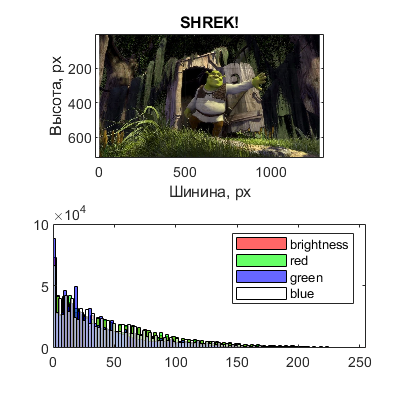


legend('brightness', 'red', 'green', 'blue')
xlim([0, 255])

saveas(f3, 'third_task.png')